## Plot the workspace of the robot (can be long if step is < 20)

step = 20;

xwork = [];
ywork = [];
zwork = [];
i=1;
q5 = 0;


for q1 = -90:step:90
    for q2 = 0:step:135
        for q3 = -145:step:0
            for q4 = -90:step:90
                L_q = [q1 q2 q3 q4 q5];
                pos = forward_kinematics(L_q);
                if (pos(1)^2+pos(2)^2+pos(3)^2)^0.5 >0
                    xwork = [xwork ; pos(1)];
                    ywork = [ywork ; pos(2)];
                    zwork = [zwork ; pos(3)];
                    i = i+1;
                end
            end
        end
    end
end    


figure (3)
set(3,'position')

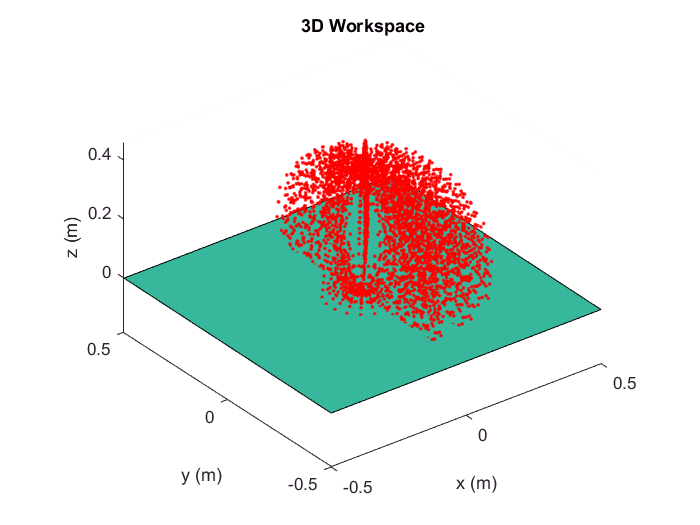

plot3(0,0,0,'o')
hold on
[xp, yp] = meshgrid(-0.5:1:0.5); % Generate x and y data
zp = zeros(size(xp, 1)); % Generate z data
surf(xp, yp, zp) % Plot the surface
plot3(xwork,ywork,zwork,'r.')  % plot the  workspace of the robot
axis equal

title('3D Workspace') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
hold off

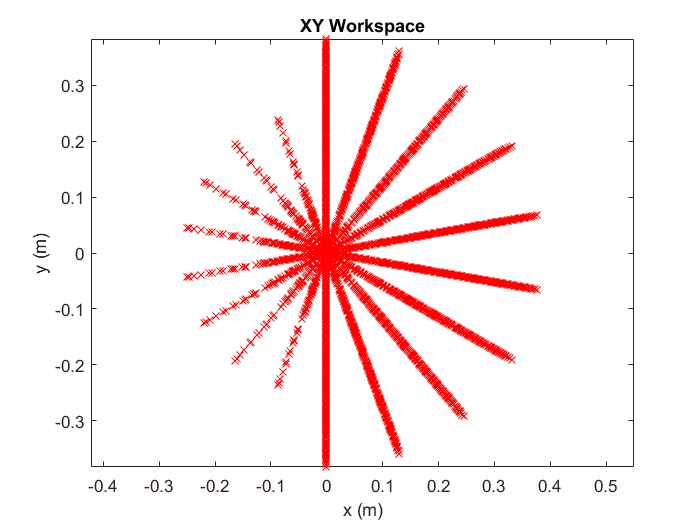



plot(xwork,ywork,'rx')
title('XY Workspace') ; xlabel('x (m)') ; ylabel('y (m)');
axis equal

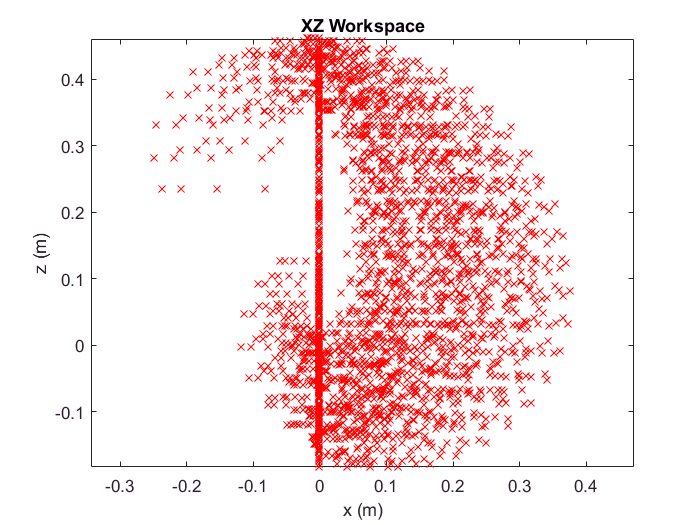




plot(xwork,zwork,'rx')
title('XZ Workspace') ; xlabel('x (m)') ; ylabel('z (m)');
axis equal

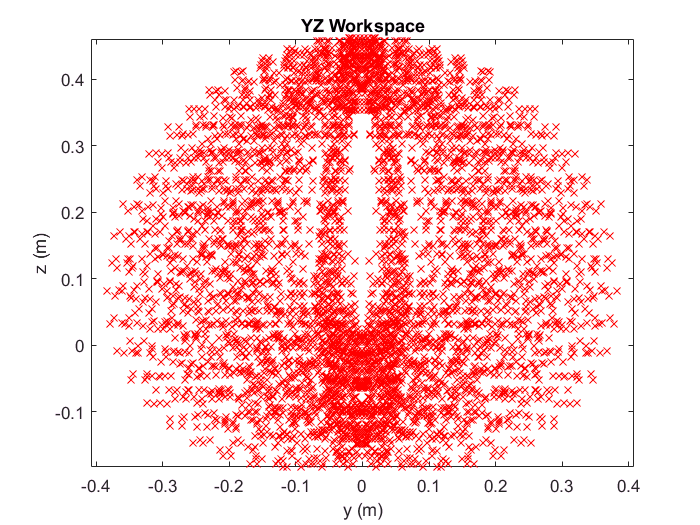



plot(ywork,zwork,'rx')
title('YZ Workspace') ; xlabel('y (m)') ; ylabel('z (m)');
axis equal

## Plot a position using Inverse Kinematics

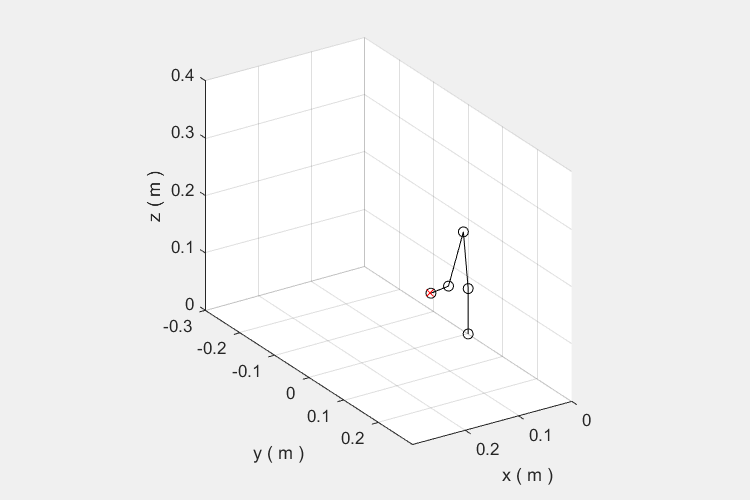

end_pose = [ 0.2  0.2  0.2  20 0];

theta_recalcule=inverse_kinematic(end_pose(1), end_pose(2) ,end_pose(3),end_pose(4),end_pose(5),1);
end_pose2 = forward_kinematics(theta_recalcule);
list2 = plot_links(theta_recalcule);

## Plot the five target positions

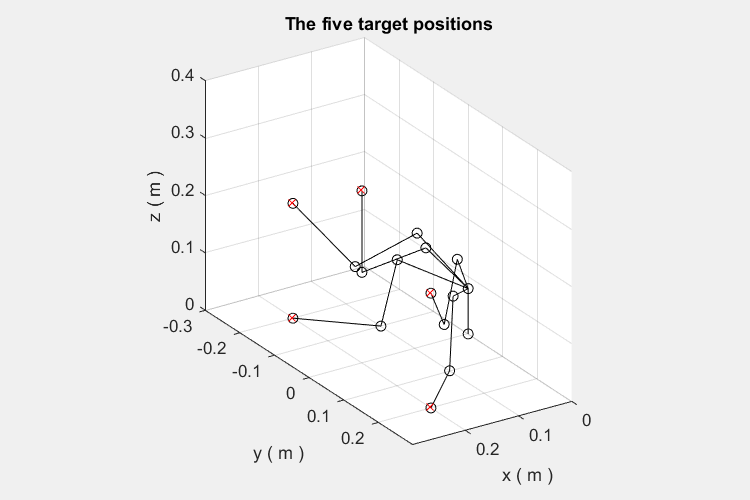

end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0];

         

hold on
set(gca,'XLim',[-0.1 0.3],'YLim',[-0.3 0.3],'ZLim',[0 0.4])
set(gcf,'Visible','on','Position', [10 10 900 600])
title('The five target positions') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
view(154,25)
grid on
for i = 1:length(end_pose)
    theta_recalcule=inverse_kinematic(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    end_pose2 = forward_kinematics(theta_recalcule);
    list2 = plot_links(theta_recalcule);
    drawnow
    
end

## Plot the animation of the robot with a free motion

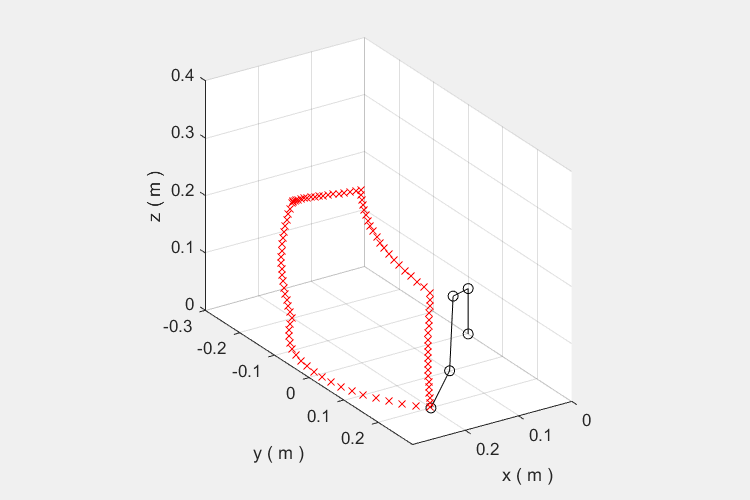


end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0];
         
nb_of_points = 20;


all_theta = [];

for i = 1:length(end_pose)-1
    
    thetas_i1=inverse_kinematic(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    thetas_i2=inverse_kinematic(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5),1);
    
    thetas_table = zeros(5,nb_of_points);
    
    for index_theta = 1:length(thetas_i1)
        spaced_thetas = linspace(thetas_i1(index_theta),thetas_i2(index_theta),nb_of_points) ;  % creates 500 points between 1 and 10 
        for index_point = 1:nb_of_points
            thetas_table(index_theta,index_point) = spaced_thetas(index_point);
        end 
    end
    
    for index_point = 1:nb_of_points
        theta_now = [thetas_table(1,index_point), thetas_table(2,index_point), thetas_table(3,index_point), thetas_table(4,index_point), thetas_table(5,index_point)];
        [list_pos,drawing] = plot_links(theta_now);
        all_theta = [all_theta ;theta_now];
        drawnow
        pause(0.002)
        delete(drawing);
        
    end
    
end

[list_pos,drawing] = plot_links(theta_now);
hold off 

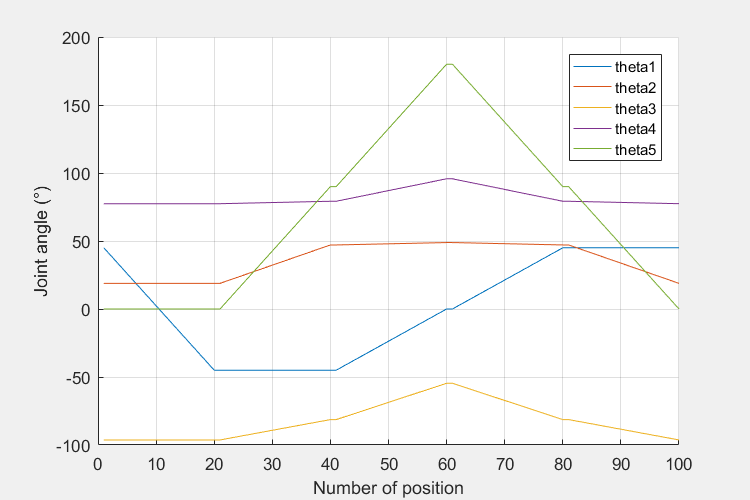

f=figure;
hold on
set( gcf,'Visible','on','Position', [10 10 600 400] );
xlabel( 'Number of position' ) ; ylabel( 'Joint angle (°)' ) ;
grid on
for i_theta=1:5
    plot(linspace(1,nb_of_points*5,nb_of_points*5),all_theta(:,i_theta))
end
legend('theta1','theta2','theta3','theta4','theta5')

## Plot the animation of the robot with a straight line trajectory

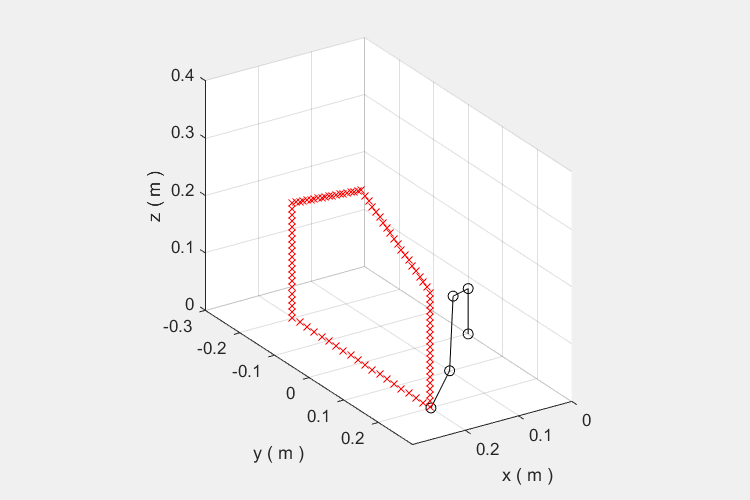



end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0];
nb_of_points = 20;
all_theta = [];
for i = 1:length(end_pose)-1
    
    thetas_i1=inverse_kinematic(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    thetas_i2=inverse_kinematic(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5),1);
    
    pos_table = zeros(5,nb_of_points);
    
 
    for index_parameter = 1:5
        spaced_parameter = linspace(end_pose(i,index_parameter),end_pose(i+1,index_parameter),nb_of_points) ;  % creates points
        for index_point = 1:nb_of_points
            pos_table(index_parameter,index_point) = spaced_parameter(index_point);
        end 
    end
    
    for index_point = 1:nb_of_points
        
        theta_now = inverse_kinematic(pos_table(1,index_point), pos_table(2,index_point) ,pos_table(3,index_point),pos_table(4,index_point),pos_table(5,index_point),1);
        all_theta = [all_theta ;theta_now];
        [list_pos,drawing] = plot_links(theta_now);
        
        
        drawnow
        pause(0.001)
        delete(drawing);
        
    end
    
end

[list_pos,drawing] = plot_links(theta_now);

hold off 

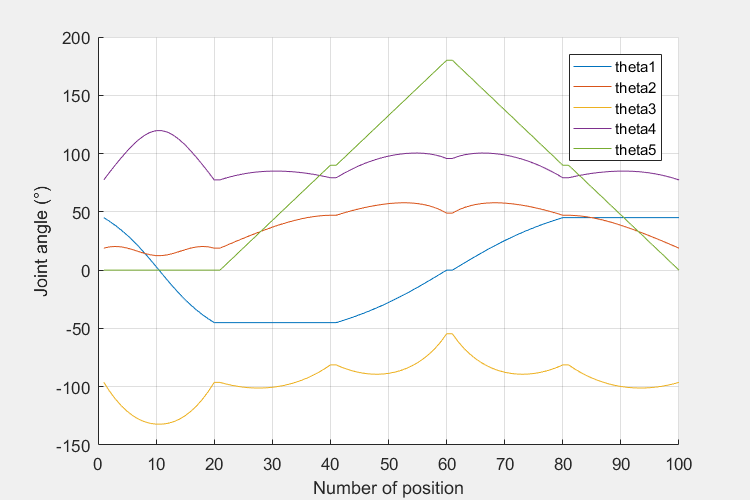

f=figure;
hold on
set( gcf,'Visible','on','Position', [10 10 600 400] );
xlabel( 'Number of position' ) ; ylabel( 'Joint angle (°)' ) ;
grid on

for i_theta=1:5
    plot(linspace(1,nb_of_points*5,nb_of_points*5),all_theta(:,i_theta))
end
legend('theta1','theta2','theta3','theta4','theta5')

## Plot the animation of the robot with a straight line trajectory avoiding an obstacle

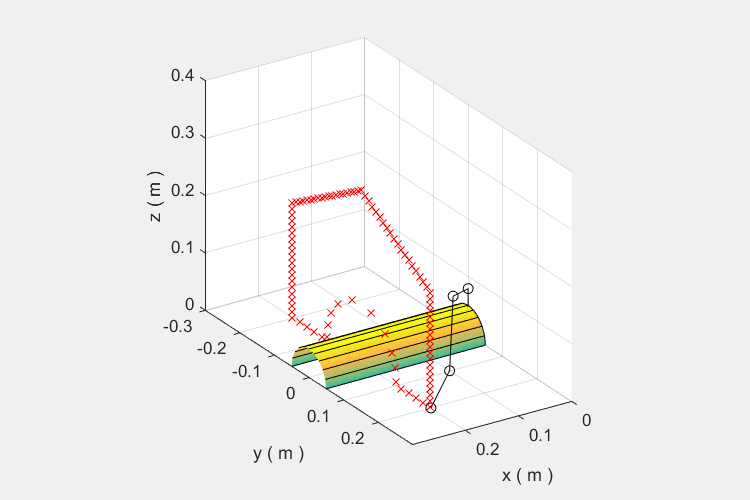


end_pose = [ 0.2  0.2  0    0 0;
             0.2 -0.2  0    0 0;
             0.2 -0.2  0.2  45 90;
             0.2  0    0.3  90 180;
             0.2  0.2  0.2  45 90;
             0.2  0.2  0    0 0];
         
nb_of_points = 20;

r_cyl = 0.05;

plot_obstacle(r_cyl);
all_theta = [];
for i = 1:length(end_pose)-1
    
    thetas_i1=inverse_kinematic(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5),1);
    thetas_i2=inverse_kinematic(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5),1);
    
    pos_table = zeros(5,nb_of_points);
    

    for index_parameter = 1:5
        spaced_parameter = linspace(end_pose(i,index_parameter),end_pose(i+1,index_parameter),nb_of_points) ;  % creates points
        for index_point = 1:nb_of_points
            pos_table(index_parameter,index_point) = spaced_parameter(index_point);
        end 
    end
    
    for index_point = 1:nb_of_points
        dist_to_cylinder = (pos_table(2,index_point)^2 + pos_table(3,index_point)^2)^0.5;
        while dist_to_cylinder < 2*r_cyl
            pos_table(3,index_point) = pos_table(3,index_point) + 0.002 ; 
            pos_table(2,index_point) = pos_table(2,index_point) * 1.02 ;
            dist_to_cylinder = (pos_table(2,index_point)^2 + pos_table(3,index_point)^2)^0.5;
        end
        
        theta_now = inverse_kinematic(pos_table(1,index_point), pos_table(2,index_point) ,pos_table(3,index_point),pos_table(4,index_point),pos_table(5,index_point),1);
        all_theta = [all_theta;theta_now];
        [list_pos,drawing] = plot_links(theta_now);
        
        
        drawnow
        pause(0.001)
        delete(drawing);
        
    end
    
end

[list_pos,drawing] = plot_links(theta_now);

hold off 

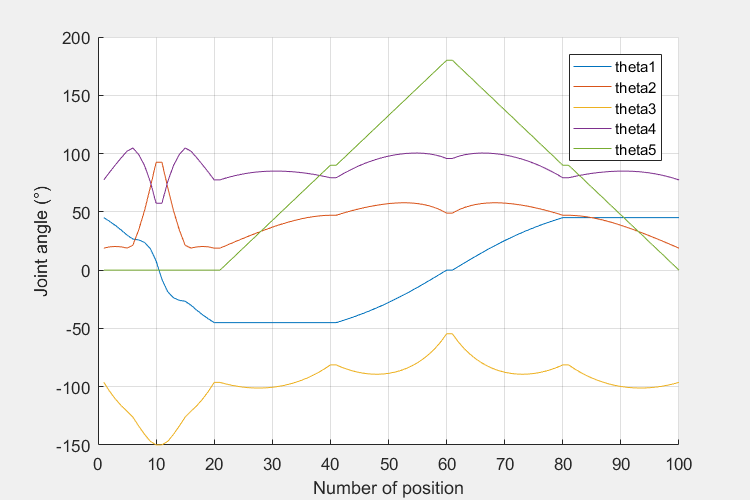

f=figure;
hold on
set( gcf,'Visible','on','Position', [10 10 600 400] );
xlabel( 'Number of position' ) ; ylabel( 'Joint angle (°)' ) ;
grid on
for i_theta=1:5
    plot(linspace(1,nb_of_points*5,nb_of_points*5),all_theta(:,i_theta));
end
legend('theta1','theta2','theta3','theta4','theta5')